Demo code for Figure 6 of Idesis (2022) - Edge centric analysis of stroke patients. An alternative approach for biomarkers of lesion recovery

Edge-centric code adapted from Faskowitz, J. et al (2020) and Zamani Esfahalani (2020)

(https://github.com/brain-networks)

Adapted by: Sebastian Idesis - sebastian.idesis@upf.edu (Feb 2022)

Initialize script

clear all;close all;clc; %Close everything
nodes = 200; % Amount of nodes from the dataset

Add helper functions and data to path

addpath('Functions');
addpath('Data');

Load regional time series

load data/ts.mat %Demo data (Taken from https://www.brainnetworkslab.com/coderesources)

Create fake data of 5 stroke patients

amount_of_patients= 5; %Number for demo
for subj = 1:amount_of_patients
    ts_patients(:,:,subj)= ts.*(randn(1200,200)*4); %original ts plus a bigger factor random amount to make every subject different
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%ENTROPY CALCULATION %%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Load data for entropy calculation - Patients according to hemisphere

ts_patients_entropy_left=[]; % initialize variable
ts_patients_entropy_right=[]; % initialize variable
hemisphere=randi([1 2],1,amount_of_patients); %Random variables where each subject is either 1 (left damage) or 2 (right damage)
for subj = 1:amount_of_patients 
    ts_toload_patients = zscore(ts_patients(:,:,subj)); %z-score time series of each subject
    if hemisphere(subj)==1
        ts_patients_entropy_left = [ts_patients_entropy_left ts_toload_patients'];  %accumulate all the time series for next analysis
    elseif hemisphere(subj)==2
        ts_patients_entropy_right = [ts_patients_entropy_right ts_toload_patients'];  %accumulate all the time series for next analysis
    end
end


Entropy calculation - Patients with left damage

% create edge time series from regional time series
ts_patients_entropy_left = ts_patients_entropy_left';
[T_patients,N_patients] = size(ts_patients_entropy_left);
M_patients = N_patients*(N_patients - 1)/2; 
ets_patients = fcn_edgets(ts_patients_entropy_left,1); % this step does the z-scoring and element-wise products. the output is a [time x edge] matrix.
% run kmeans -- note that in principle any clustering algorithm can be
% applied to edge time series or the efc matrix
k = 10; 
ci_patients= kmeans(ets_patients',k,...
    'distance','sqeuclidean',...
    'maxiter',1000);
% map edge communities into matrix
mat_patients = zeros(N_patients);
mat_patients(triu(ones(N_patients),1) > 0) = ci_patients; % this step gives you the indices of each edge
mat_patients = mat_patients + mat_patients';

%% calculate normalized entropy
[u_patients,v_patients] = find(triu(ones(N_patients),1)); % this step gives you the indices of each edge
[~,enorm_patients_left] = fcn_node_entropy(ci_patients,u_patients,v_patients,N_patients);

Entropy calculation - Patients with right damage

% create edge time series from regional time series
ts_patients_entropy_right = ts_patients_entropy_right';
[T_patients,N_patients] = size(ts_patients_entropy_right);
M_patients = N_patients*(N_patients - 1)/2; 
ets_patients = fcn_edgets(ts_patients_entropy_right,1); % this step does the z-scoring and element-wise products. the output is a [time x edge] matrix.
% run kmeans -- note that in principle any clustering algorithm can be
% applied to edge time series or the efc matrix
k = 10; 
ci_patients= kmeans(ets_patients',k,...
    'distance','sqeuclidean',...
    'maxiter',1000);
% map edge communities into matrix
mat_patients = zeros(N_patients);
mat_patients(triu(ones(N_patients),1) > 0) = ci_patients; % this step gives you the indices of each edge
mat_patients = mat_patients + mat_patients';

%% calculate normalized entropy
[u_patients,v_patients] = find(triu(ones(N_patients),1)); % this step gives you the indices of each edge
[~,enorm_patients_right] = fcn_node_entropy(ci_patients,u_patients,v_patients,N_patients);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%Visualization%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%To perform brain area analysis replace the hemisphere variable for a new one indicating if the injury is cortical or sub-cortical

Make figures to visualize

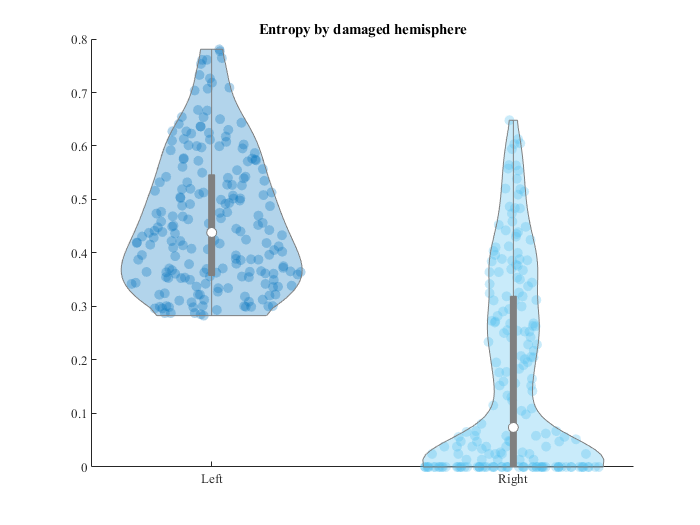

figure()

group = [zeros(1,length(enorm_patients_left)),...
    ones(1,length(enorm_patients_right))]; %Create groups for violin plot

temp_combined = [enorm_patients_left' enorm_patients_right' ]; 
vs = violinplot(temp_combined, group); %Plot violin
xticklabels({'Left','Right'}); a = get(gca,'XTickLabel'); set(gca,'XTickLabel',a,'FontName','Times','fontsize',8);
title('Entropy by damaged hemisphere')